clc; clear all; close all;

img_path = fullfile('Codes','fundus_images'); % Definir la ruta relativa de las imagenes RFI.
metadata_path = fullfile('data', 'metadata', 'metadata.csv'); % Definir la ruta relativa de la tabla metadata.
T = readtable(metadata_path);

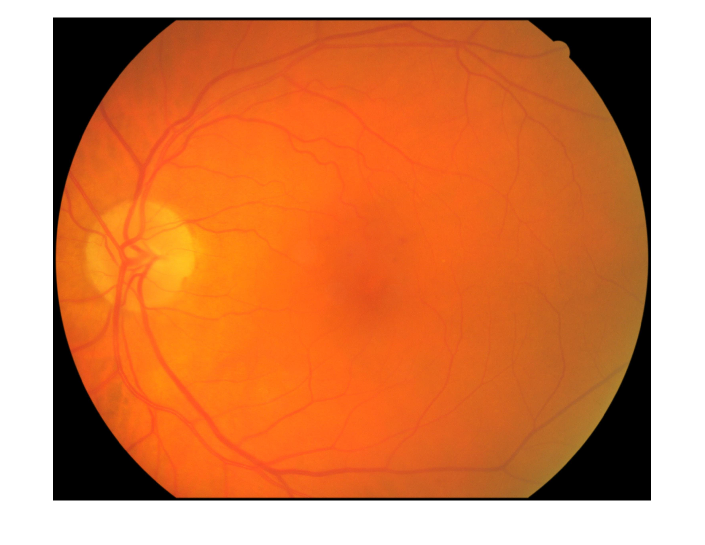

RGB = imread(string(fullfile(img_path, T{1,1})));%Aquí elijes la imagen
R=RGB(:,:,1);
G=RGB(:,:,2);
B=RGB(:,:,3);
maxR=max(R(:));
maxG=max(G(:));
maxB=max(B(:)); 
figure;
imshow((RGB));

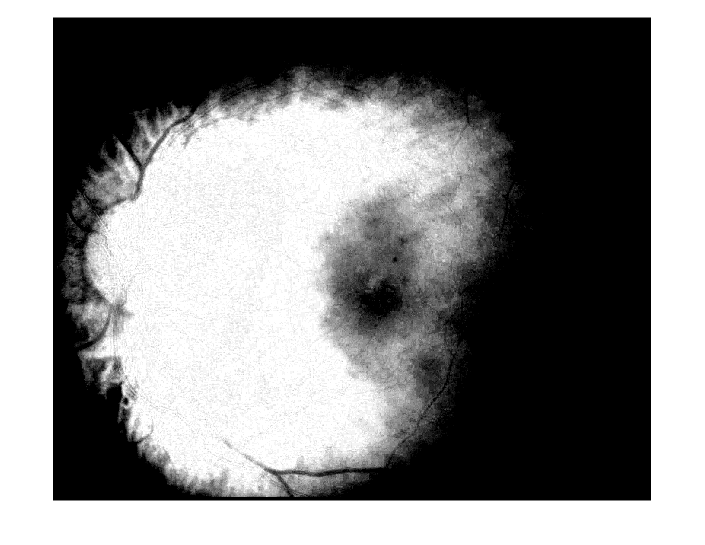

figure;
imshow(RGB(:,:,1),[0.9*maxR maxR]);

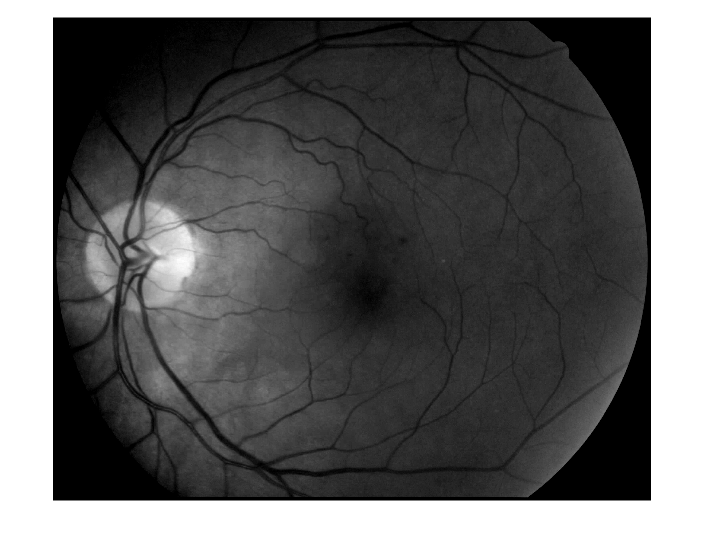

figure;
imshow(RGB(:,:,2),[0.4*maxG maxG]);

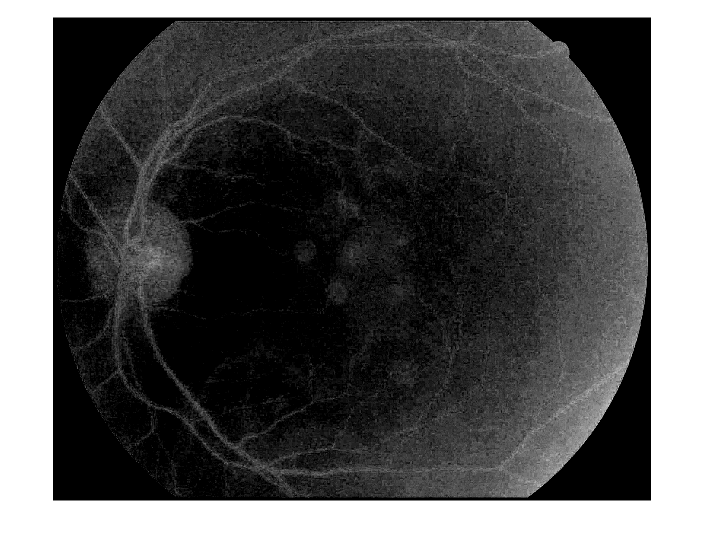

figure;
imshow(RGB(:,:,3),[0.4*maxB maxB]);

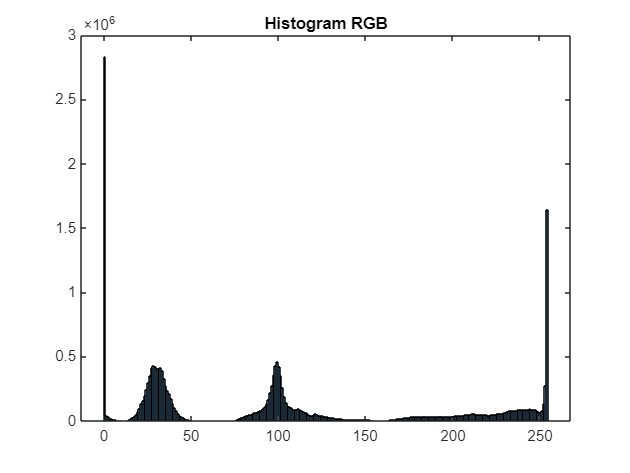

figure;
h1=histogram(RGB);
title('Histogram RGB');

m1=mode(RGB(:));
if m1==0;
   RGB2=RGB;
   RGB2(ismember(RGB2, 0)) = [];
   m2=mode(RGB2)
   if m2==255
      ji=1
   end
        %sigue con el resto de pasos
end

m2 = uint8
255

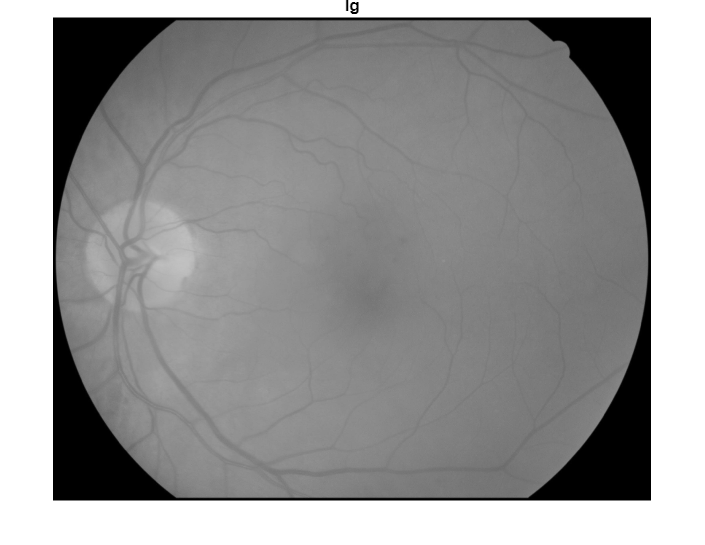

Ig=rgb2gray(RGB);
%Ig=B;
imshow(Ig);
title('Ig');

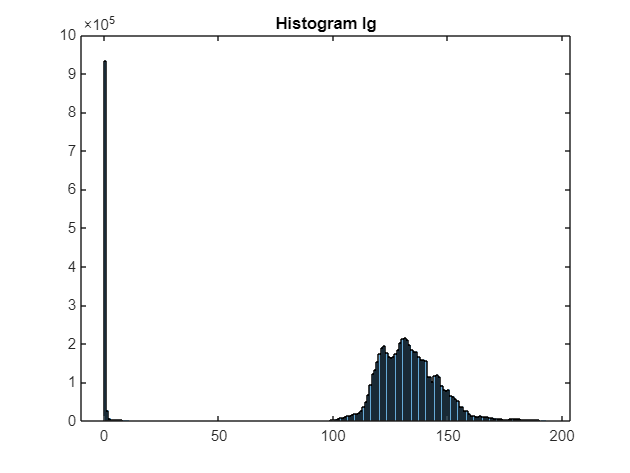

figure;
histogram(Ig);
title('Histogram Ig')

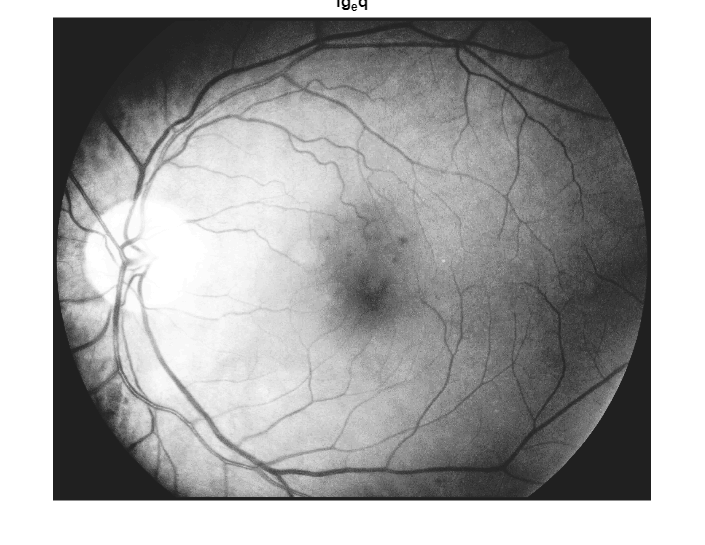


Ig_eq=histeq(Ig);
figure;
imshow(Ig_eq);
title('Ig_eq')

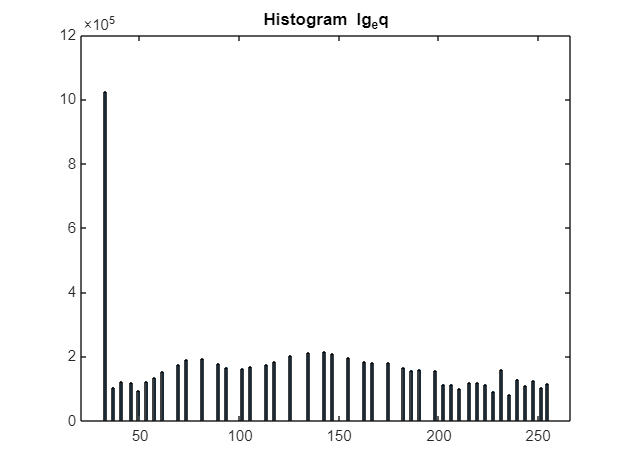

figure;
histogram(Ig_eq);
title('Histogram Ig_eq');

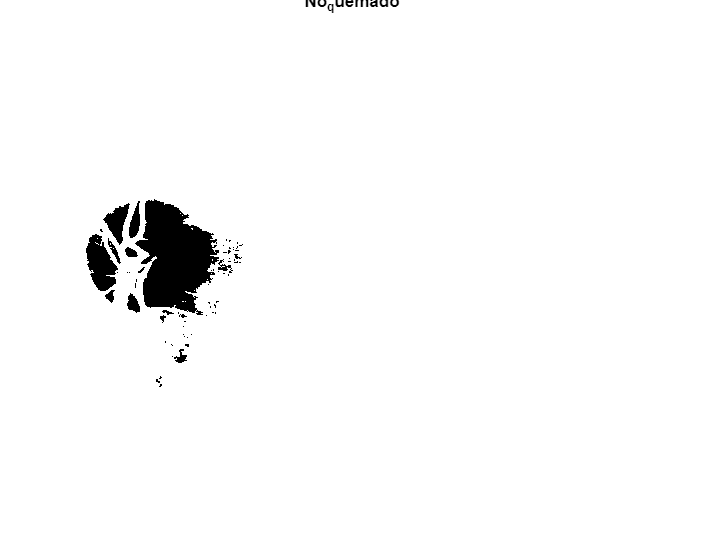


No_quemado=Ig_eq<250;
figure;
imshow(No_quemado);
title('No_quemado');

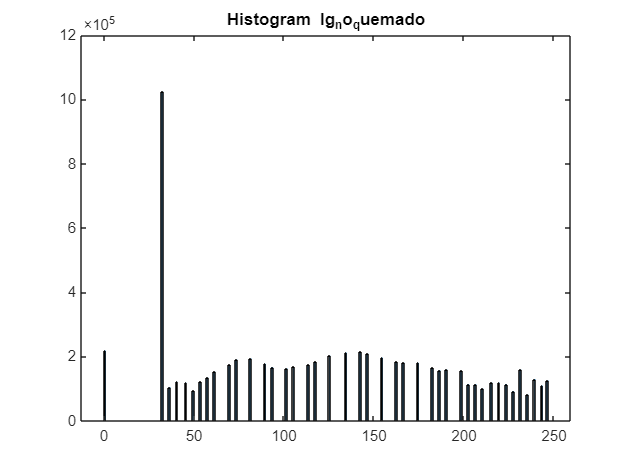


Ig_no_quemado=double(Ig_eq).*No_quemado;
figure;
histogram(Ig_no_quemado);
title('Histogram Ig_no_quemado');

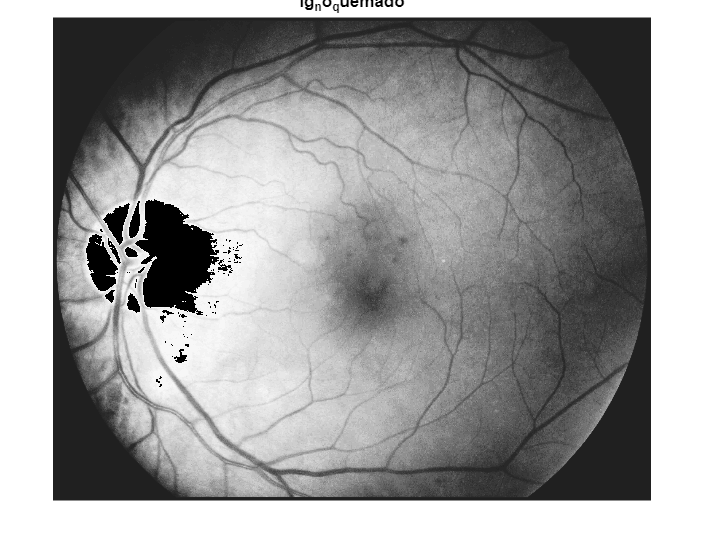

figure;
imshow(uint8(Ig_no_quemado));
title('Ig_no_quemado');

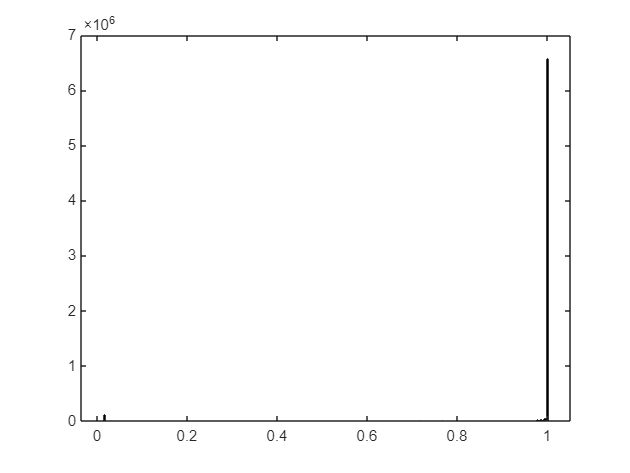


%Creo una imagen igual pero con el histograma ecualizado para contrarrestar
%los artefactos
Ig_eq=histeq(Ig_no_quemado);
%Ig_eq=double(Ig_eq);
w2 = ones(20);
Blurred = imfilter(double(Ig_eq), w2);
Blurred = imfilter(double(Blurred), w2);
Blurred = imfilter(double(Blurred), w2);
Blurred=Blurred./max(Blurred(:));
figure;
histogram(Blurred);

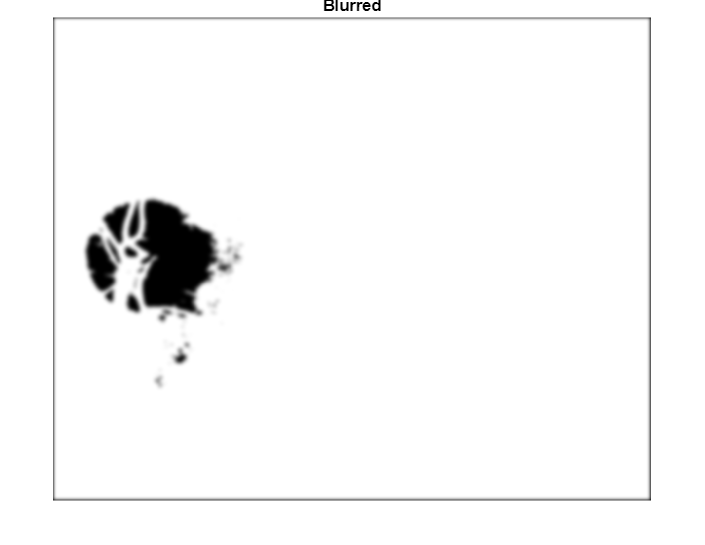

figure;
imshow(Blurred,[]);title('Blurred');

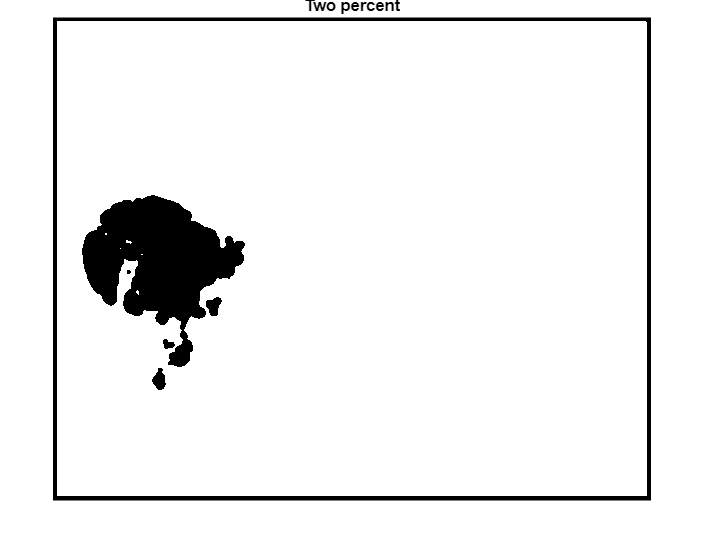


%Seleccionamos el 2% más lulminoso de la imagen
two_perc=Blurred>=0.98*max(Blurred(:));%si lo subes demasiado en algunas imagenes no da (P.e. la 857) pero si lo bajas demasiado otras no dan (P.e. la 39)

figure;
imshow(two_perc);title('Two percent');

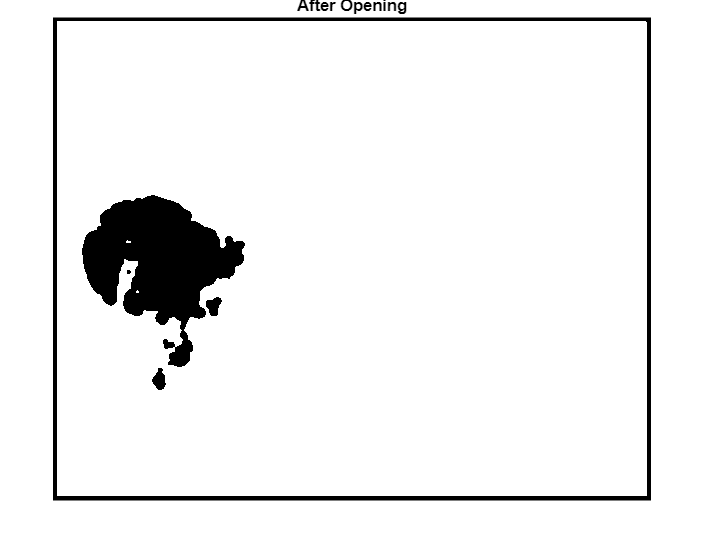


%Antes de hacer la clasificación en grupos hay que hacer un opening porque
%si no te van a dar un montón de grupos
se = strel('disk',6);%Se hace el opening con un disk (Forma redonda) del tamaño que elijas
afterOpening = imopen(two_perc,se);

figure;
imshow(afterOpening); title('After Opening');

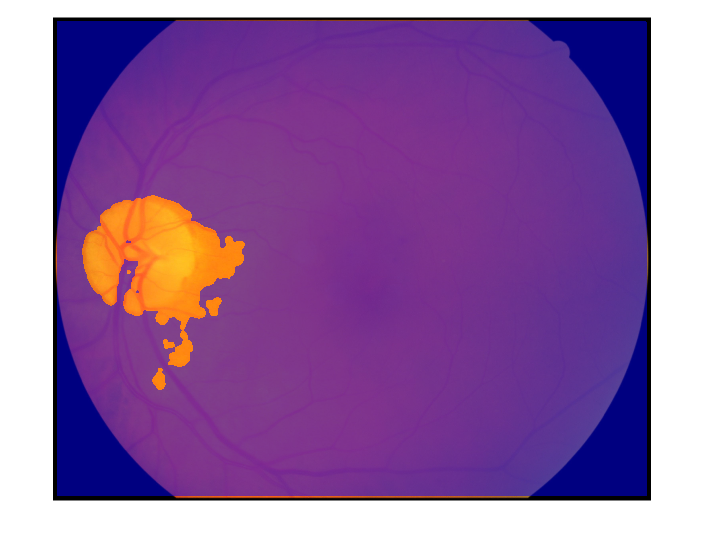


%Se ha conseguido esto:
segI=labeloverlay(RGB,afterOpening);
figure;
imshow(segI);


%Clasificamos los grupos que se han conseguido
grupos_matriz = bwlabel(afterOpening,4);
grupos = unique(grupos_matriz);% Uno de los grupos es el fondo

%Cual de los grupos ocupa más píxeles? Ese será parte del OD
conteo = histc(grupos_matriz(:), grupos);
[~, idx_ordenado] = sort(conteo, 'descend');%Esto ordena del mayor grupo al menor
grupo_mas_repetido = grupos(idx_ordenado(2));%este es el grupo del OD, se pone como el segundo grupo más grande porque el primero es el fondo
OD_location_muestra=grupos_matriz==grupo_mas_repetido;

[row, col] = find(OD_location_muestra);%Busca los elementos no 0